# Rectangular plate vibration modes identification

*This example demonstrates the use of MPIFD_MIMO on a real 2D structure, with experimental data. The experiment was conducted by François Fabre at LAM (ð'Alembert, Sorbonne Université) following a Roving hammer method, with a fixed accelerometer.*

**INSTRUCTIONS: **run section by section untill the GUI appears. Then follow the steps described to manipulate the GUI, and eventually run the last section.

close all
clear all
clc

addpath('MPIFD_MIMO')

## 1. Description of the test plate and its measurements

Measurement grid with 45 points with

`Nx = 9 `steps in X direction and  `Ny = 5 `steps in Y direction

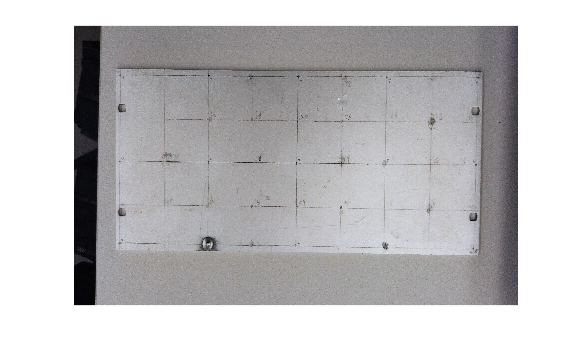

The plate has been measured with an impact hammer on each of the 45 points of the grid, while an accelerometer has been attached to the point #35. Through reciprocity, we assume symmetry of the tranfer function matrix H[j,i] = H[i,j] and we thus later describe the system as having 1 input and 45 output.

## 2. Initialization of the required user input

#### A. Let's start with loading the measurements.

Please edit the first line to make sure the relative path to the directory containing the measurement data is correct.

% LOAD MEASURES
load('plate_example/FRF_plaque_moyenne.mat')
w = 2*pi*FRF_plaque_moyenne.freq ; % frequency vector [Nf x 1]
frf=FRF_plaque_moyenne.frf_moy; % FRF matrix in the form [Nf x (NoxNi)]

#### B. Choose the frequency range of focus

We can now select a particular frequency span to focus on, for instance if measurements have too much noise above a certain frequency.

% choose the frequency range of interest for modelling: here [50 1800]
[w1, frf1] = select_frf(w, frf, 50, 1800) ;

#### C. Setting up the various options and information necessary for the computation and the display

% define the type of measurement: here, accelerance
frfType = 'acc' ;

% Computation using complex-valued residues (by changing to 'true' we can
% opt for real-valued residues only)
useRealResidues = false ;

% Do we want to use the corrective terms LR/UR for out of band modes?
useLRUR = true ;

% Description of the system : index of the DOFs with actuators and sensors
vectAct = 35 ;
vectSens = 1:45 ;
nPts = 45;

% FRF(s) to display
% DOF for actuation: 35, DOF for sensor: 35
% We choose to display the colocalised response function H[35,35]
listIOVisu = [35 35];

% List of orders to try for drawing the stabilization chart
order = 10:5:100 ;


#### D. Definition of the mesh for mode shapes visualization

Let us load the coordinates of the measurement points on the plate:

% Loading coordinates of the DOFs in a frame of reference
load('plate_example/coord_points_plaque.mat') ;
x=reshape(x_y_plaque(:,1),5,9)';
x=x(:);
y=reshape(x_y_plaque(:,2),5,9)';
y=y(:);

COORD = [x,y] ;

For mode shape visualization there are two options here:

- Either opt for 2D geometry description, and we assume a flat surface

- Opt for a 3D geometry description.

Both options are presented below, mostly to show how the 3D visualization works. You can comment/toogle one or the other.

- **Option 1 : flat, 2D surface definition**

% Opting for 2D flat geometry description
meshStructure.dimension=2;
% Coordinates of the points in [x1,y1 ; x2,y2 ; ... ; xn,yn] form
meshStructure.COORD=COORD;

- **Option 2 : using 3D object definition**

% sizeX = size(x') ;
% % Generate a list of rectangular 'faces' that pave the plate
% faces=[];
% nY=numel(unique(y));
% nX=numel(unique(x));
% for ii=1:nY-1
%     for jj=1:nX-1
%         faces = [faces, [(ii-1)*nX+jj ; (ii-1)*nX+jj+1 ; ii*nX+jj+1 ; ii*nX+jj]] ;
%     end
% end
% % % Generating the structure needed for MPIFD_MIMO
% % Informing that the model is 3D
% meshStructure.dimension = 3 ;
% % list of points (vertices)
% meshStructure.model3D.vertices = [x' ; y' ; zeros(sizeX)] ; 
% % normal to the surface in each point
% meshStructure.model3D.vertexNormals = [zeros(sizeX) ; zeros(sizeX) ; ones(sizeX)] ;
% % list of faces
% meshStructure.model3D.faces = faces ; 
% % information on the direction of measurement (do not change unless you have used for instance 2- or 3-axis accelerometer)
% meshStructure.model3D.frfModelLink = [(1:nPts)', ones(nPts,1)] ; 

## 3. Starting the GUI

%% launch the GUI and start the identification

fig1 = mpifd_mimo(w1, frf1, vectAct, vectSens, order, ...
    useLRUR, useRealResidues, frfType, listIOVisu, meshStructure) ;

The GUI should start and compute the poles of the system for each order in the list provided using the *LSCF algorithm* [1-3]. The stabilization chart is displayed in the top plot, and the measured FRF (magnitude and phase) chosen for display are shown in the lower plot as follows:

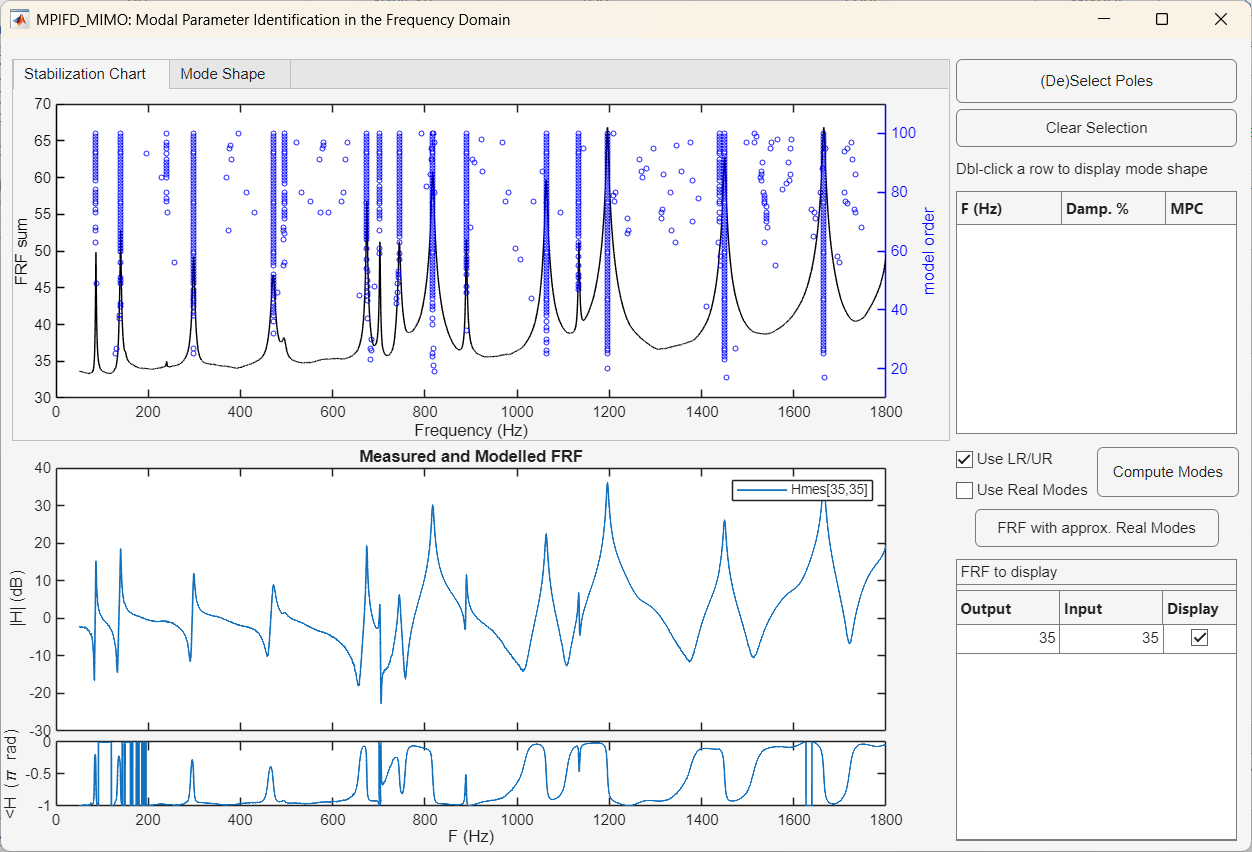

## 4. Using the GUI

- Click on the "(De)Select Poles" button on the top right corner of the GUI

- The mouse cursor turns into a cross-hair, you can start clicking on the poles (blue circles) that seem stable enough (continuous, straight vertical line). In the present case, there are lots of resonances. Some of them are close to each other, but you can zoom in to click them separately, then zoom out again.

- After selecting the desired poles, click on "Validate selection" (same button) and the mouse cursor turns back to normal.

Select the first 10 poles (see below) and validate. The list of selected poles appears gradually in the top table on the right (highlighted in green). You can zoom in (using the zoom tool on the top-right of the plot) on the stabilization diagram and see that the 10th mode shows a double pole for the identification with order 100. Thus we selected a pole from an order slightly lower, when the identification gives a single pole for that mode. (Mind that you click again the zooming tool to revert to selection mode).

The lower table (highlighted in yellow) allows to hide/show any of the FRFs in the plot thanks to the right-side checkboxes. With a right click you can also permanently delete a row, or add a row. You can also edit manually the table to change which FRFs are displayed.

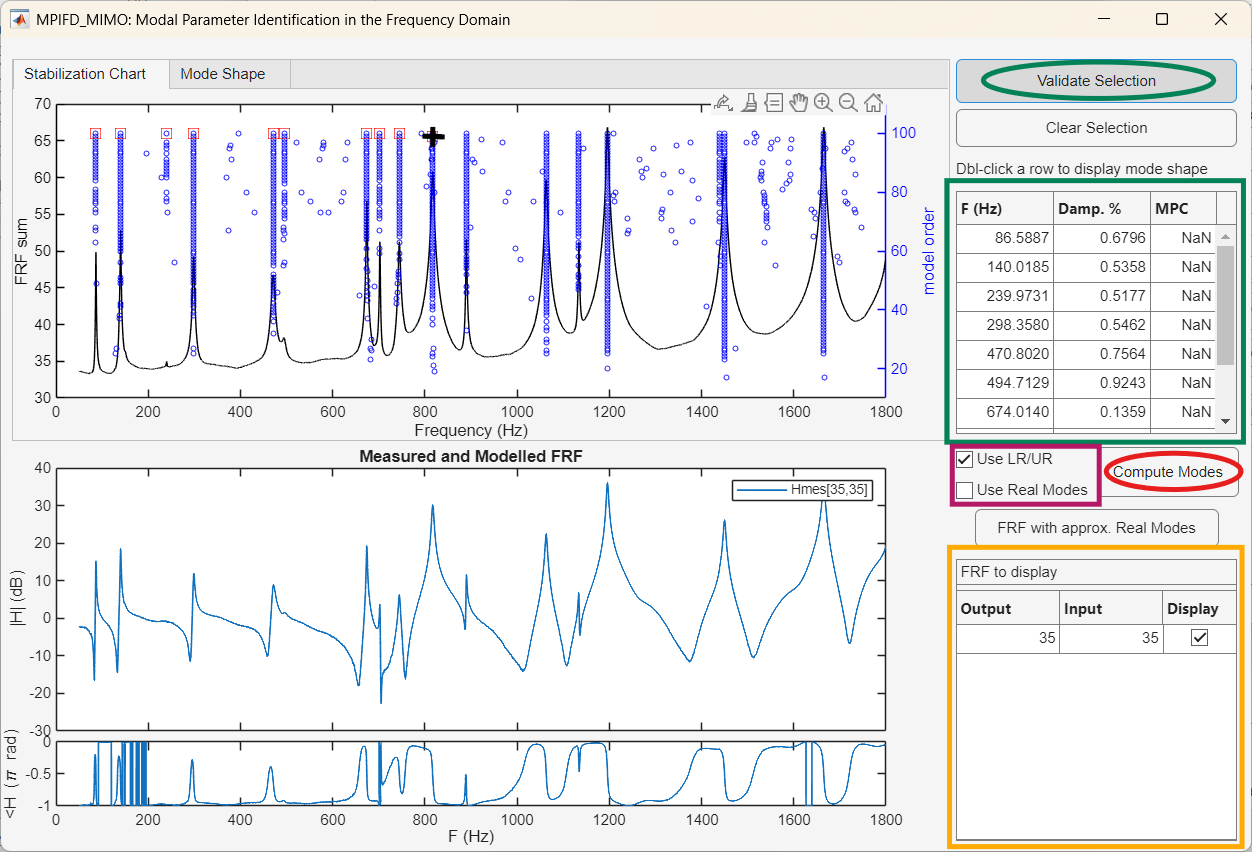

## 5. Computing modes and FRFs

Residues needed to estimate the modal FRFs are computed using the well-known LSFD algorithm [4]. There are several options for computing modal FRFs based on the identified poles. Two checkboxes allow for setting these options (highlighted in purple):

- The checkbox "Use LR/UR" allows the user to activate or deactivate the use of additional terms **LR** and **UR**, which model the effect of out-of-band modes, and can thus better represent the FRFs in the frequency band of interest.

- The checkbox "Use Real Modes" allows to chose between complex-valued residues (more general case), or real-valued residues (which constrains the problem). Systems with well uncoupled modes will work well with real residues, while if some mode coupling is present or the damping is not proportional, certain modes will be complex-valued. Complex-valued residues produce complex-valued modes, which allow for testing if the pole is a physical one or a mathematical one, using various techniques.

Once the options chosen (by default, none of the checkboxes are selected), **click on "Compute Modes"** (highlighted in red) to start the computation of residues and modes, based on the selection of poles.

The plot in the lower part of the window now shows an additional curve with dotted lines, corresponding to the modal FRF computed. 

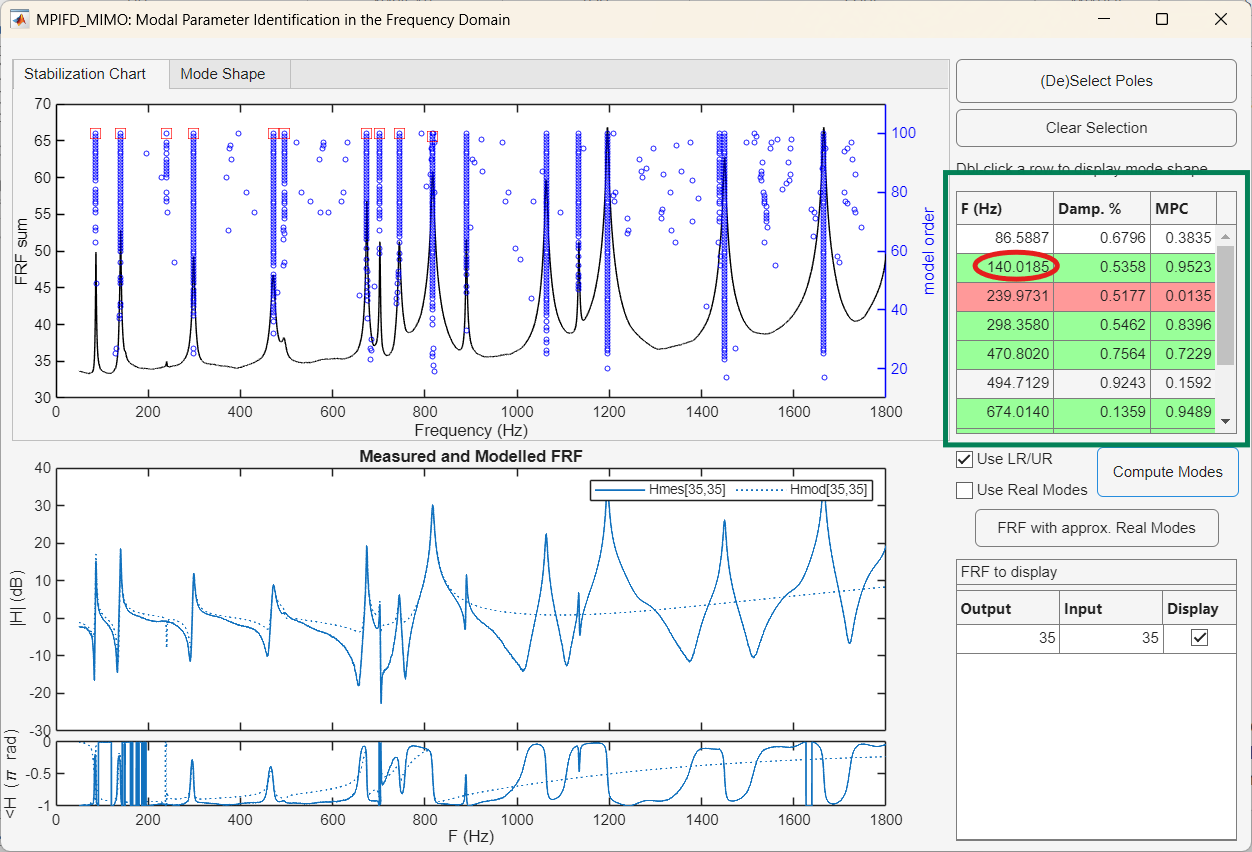

If the computation was done using complex modes, the Modal Phase Colinearity [5] parameter (with a value between 0 and 1) is computed and shown in the upper table. Modes with a high MPC are highlighted in green, and are likely to be linked to physical poles, while modes with very low MPC are highlighted in red and have either poor measurement or could correspond to mathematical poles. In this example, some modes seem to have perfect MPC, meaning that they are real-valued, despite being computed with complex residues, which reflects a good modal fit, uncoupled modes, and proportional damping.

In this case, the FRF does not fit perfectly, but certain modes seem to have a good MPC nonetheless. Incidently, we can see that the 3rd and 6th modes have bad MPC. They are also modes with very little amplitude in the overall response (the sum of absolute values of real and imaginary parts of all the FRFs measured) and barely appear at all in the colocalized FRF. The first mode seem to fit but the phase information is very noisy in the measurement, which probably affects the accuracy of the residue and mode shape calculation, hence a not-so-good (but also not-so-bad) MPC value. The second mode looks well captured and has a high MPC value.

## 6. Modal FRF using approximated real-valued modes

One by-product of the LSFD routine used for computing residues and mode shapes with complex-valued coefficients is an approximation of real-valued modes. Thus one easy way to re-estimate the modal FRFs is to use this part of the results. For this we just need to hit the "FRFs with approximated Real Modes" button.

This only changes the modal FRF that is displayed in the lower plot. Some of the modes seem to have a better fit, but in this case there is not a big diffrerence, and the parts in between the modes (low magnitude) look maybe even worse.

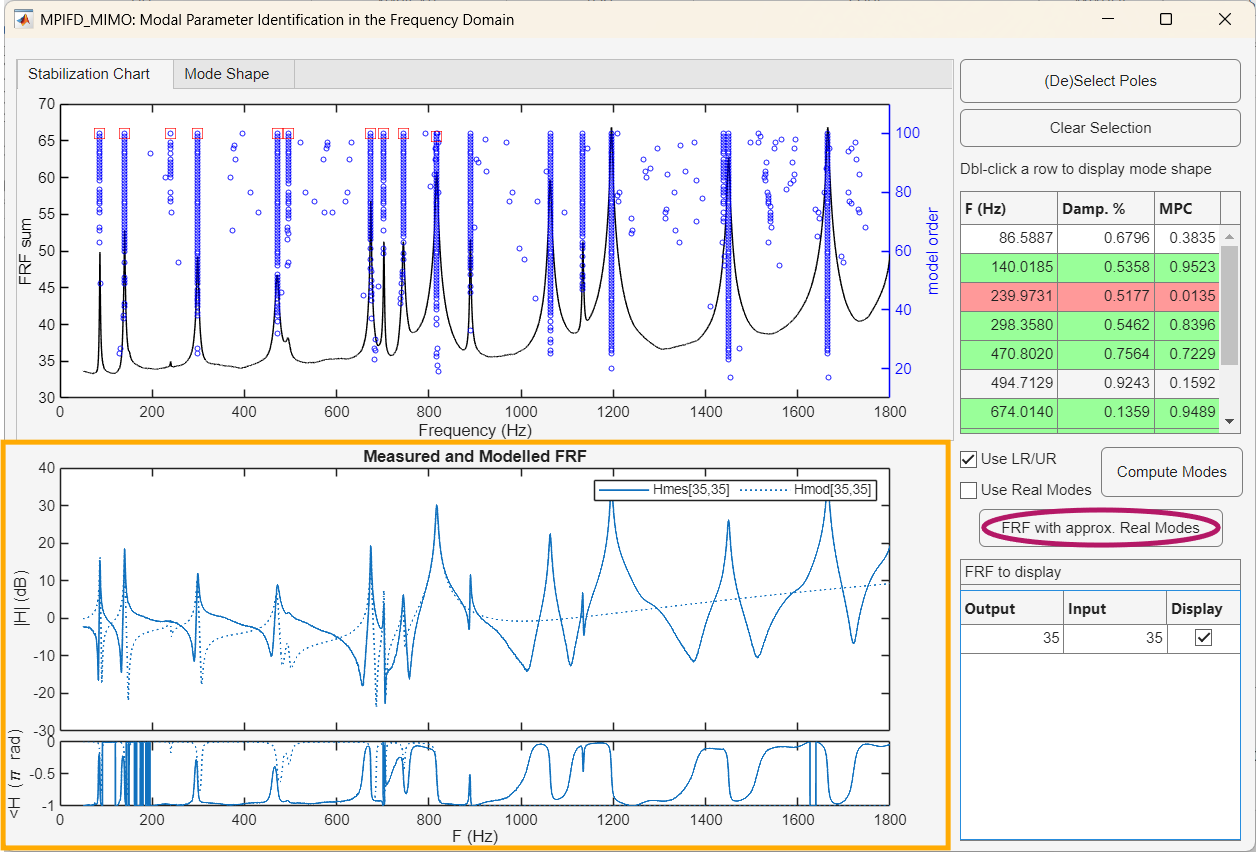

## 7. Re-computing modes using real-valued coefficients only

Another way is to force the whole residue computation process (LSFD routine) to use real-valued coefficients. For that we check the "Use Real Modes" box, and we hit again the "Compute Modes" button.

In this case the result on the modelled FRF is much better. However in this case only real-valued modes are computed, by nature, so we cannot compute an MPC index to evaluate the quality of the mode.

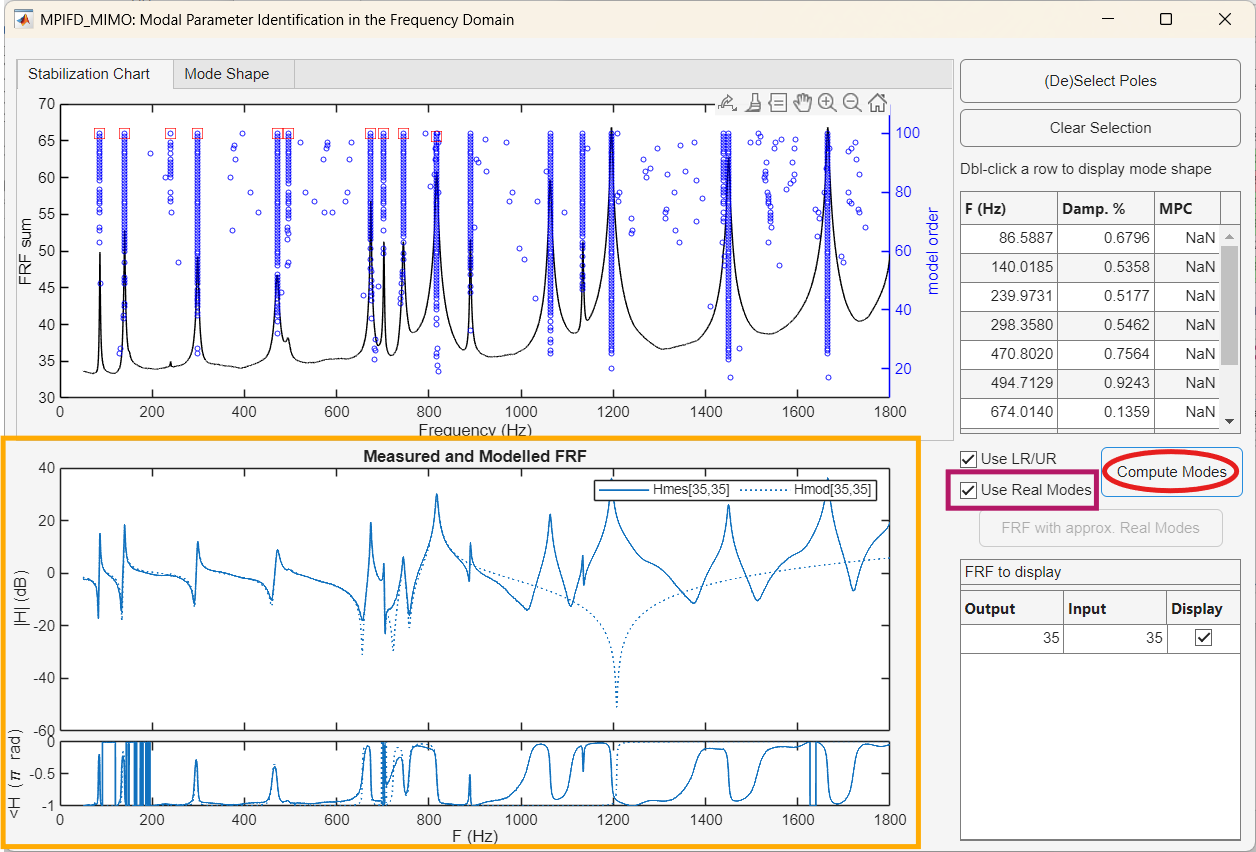

## 8. Visualizing mode shapes

By double-clicking on one mode in the upper table, the upper plot switches to the second tab and displays the mode shape. 

We choose here the second, because it had a good result both with complex of real-valued calculations. It shows a nice (1,1) flexural plate mode.

Actuator and sensor (relating to the displayed FRFs) locations are shown with respectively red square markers, and round blue markers. Here in the same point, since we are displaying the colocalised FRF: H[35,35].

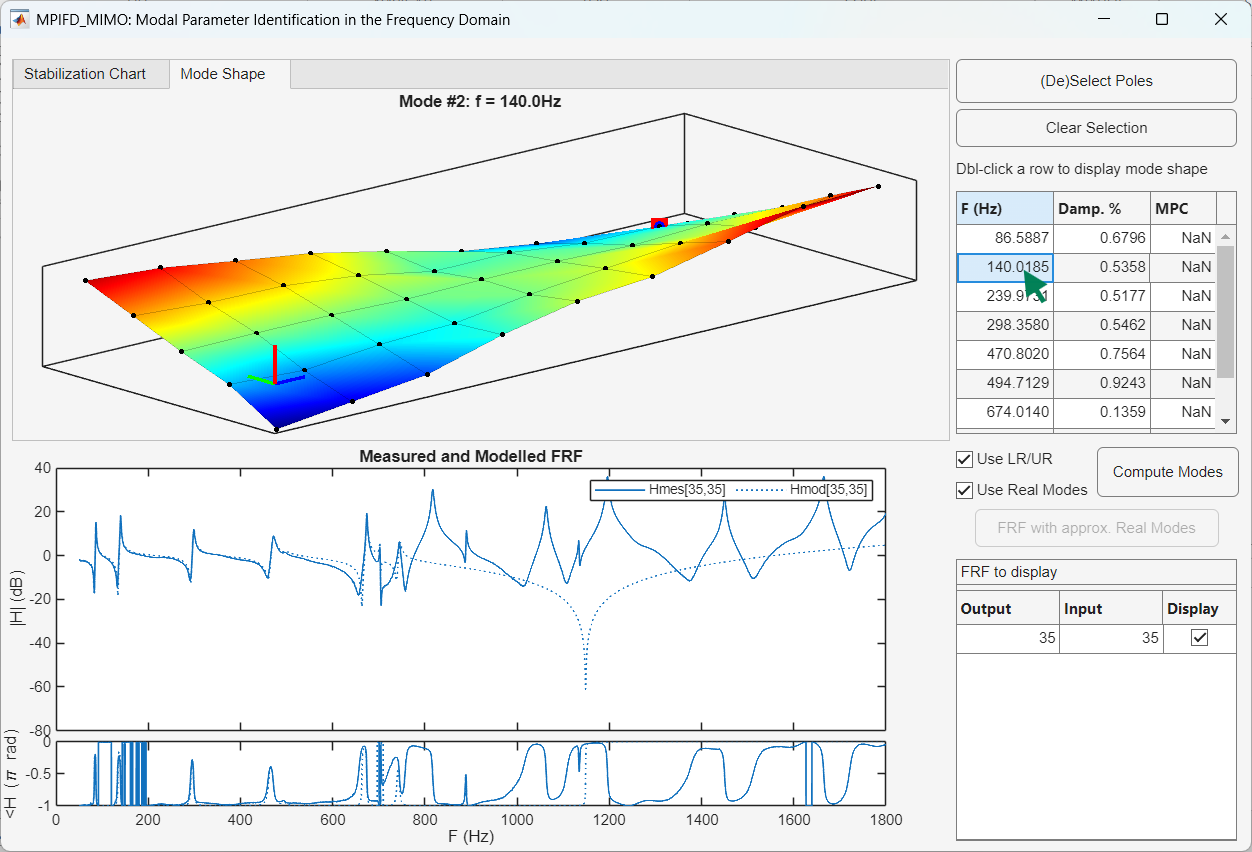

To change the aspect ratio of the figure, one must change the value of the parameter `dFactor` and replot the mode. To do this, one must shall the command line:

st=guidata(fig1);
st.dFactor = st.dFactor*2;
guidata(fig1,st);

After which one can double click again on the desired mode to update the plot:

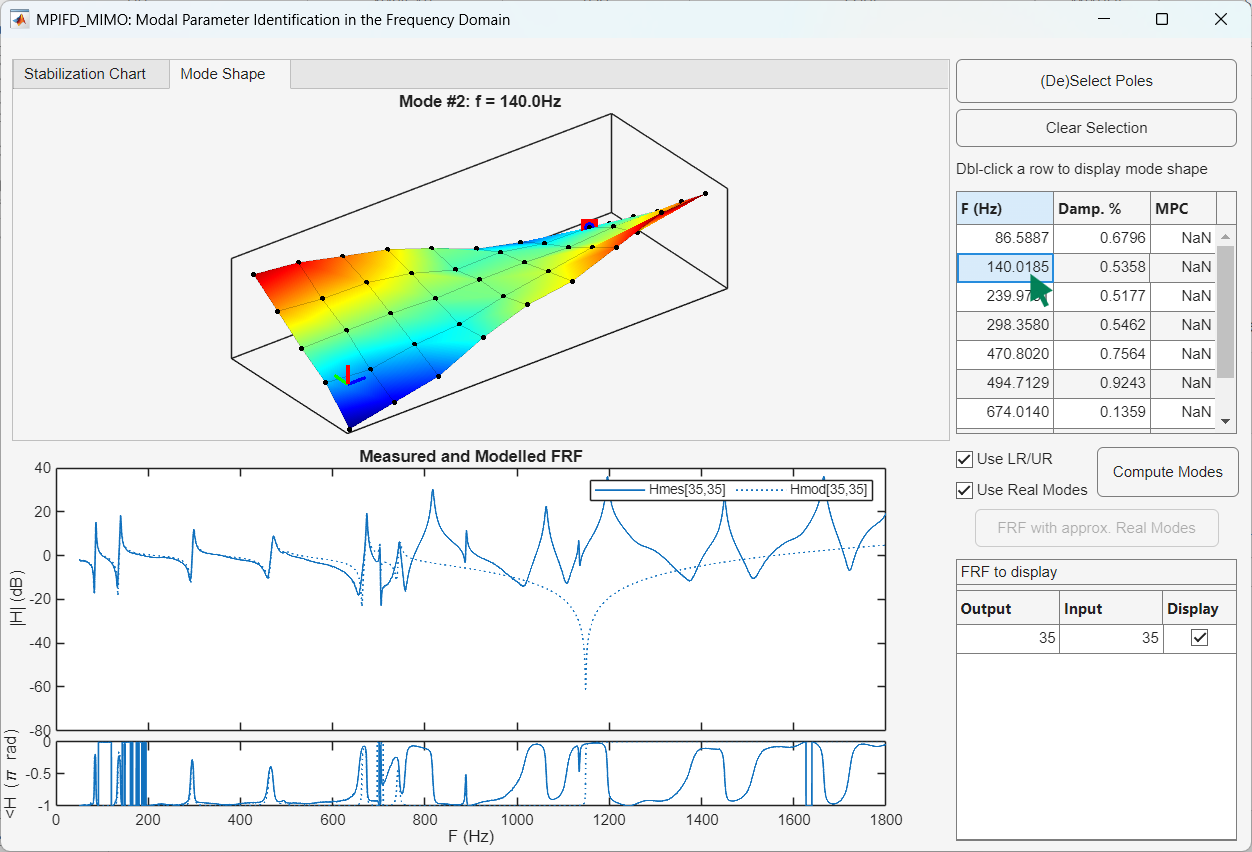

## 4. Manual takeover

We can also interact with the model through the console. For this, we need to extract the data and handles from the GUI.

%% Manual takeover
st = guidata(fig1);

One can access the identified parameters, for instance the mode frequencies `fst`, and their respective dampings `xist`, as well as the corresponding residues `rntot` and the mode shapes `phi` (possibly compex valued) and `phir` (real-valued).

% show frequency and damping of the 10 identified modes
disp([st.id.fst st.id.xist])

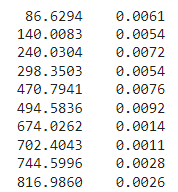


% show all the available fields of st.id
disp(st.id)

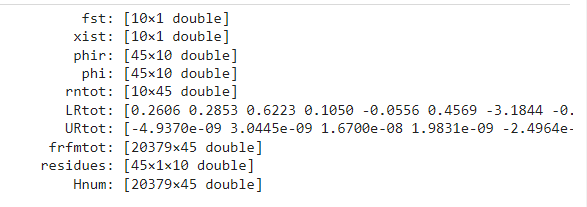

To know more about the data available in the `st.id` structure, you can have a look at the description of the `lsfd.m` routine:

help lsfd

## Credits

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors :
% Baptiste Chomette, Ecole Centrale de Lyon, LTDS, baptiste.chomette@ec-lyon.fr
% Jean-Loic Le Carrou : Sorbonne Université, d'Alembert, jean-loic.le_carrou@sorbonne-universite.fr
% Sami Karkar : Sorbonne Université, d'Alembert, sami.karkar@free.fr
% François Fabre : Sorbonne Université, d'Alembert, fabrefrancois8@gmail.com
%
% Aknowledgements :
% This work, part of the project Ngombi, was funded by the Agence Nationale de la Recherche
% (French National research agency), Grant No. ANR-19-CE27-0013-01.
%
% License :
% GNU CC BY-NC-SA
%
% Realease : v0 ... 2025
%
% Reference : 
% B. Chomette, J-L. Le Carrou, S. Karkar, F. Fabre, ..., JOSS, ...
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



## *References*

[1] Van der Auweraer H., P. Guillaume, P. Verboven and S. Vanlanduit, “Application of a Fast-Stabilizing Frequency Domain Parameter Estimation Method,” *ASME Journal of Dynamic Systems, Measurement and Control*, vol. 123, no. 4, pp. 651-658, December 2001.

[2] Polyref

[3] Balmes, MSSP 1997

[4] Sandro Amador, Mahmoud El-Kafafy et al, A New Maximum Likelihood Estimator Formulated in Pole-Residue Modal Model, Applied Sciences 9, 3120, 2019, doi:10.3390/app9153120

[5] Richard S. Pappa, Kenny B. Elliott, and Axel Schenk, "Consistent-mode indicator for the eigensystem realization algorithm. *Journal of Guidance, Control, and Dynamics*, 16(5):852–858, Spetember–October 1993.